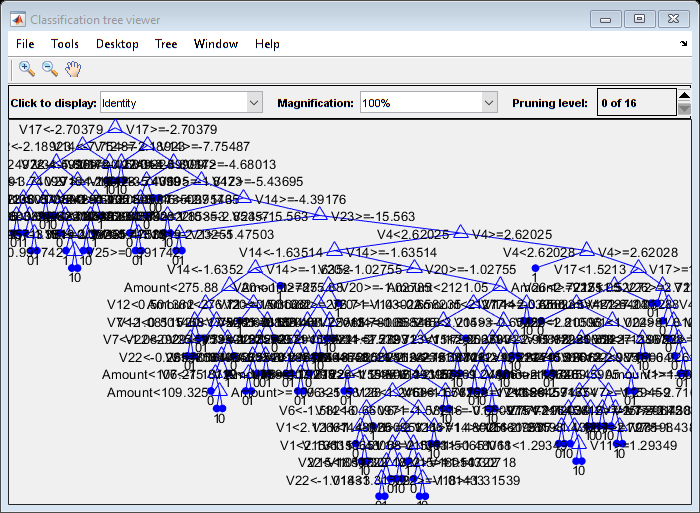

clear;
clc;
rng(0);

T = readtable('creditcard');
    T.Class = categorical(T.Class);
    T.Time = [];

cvp = cvpartition(T.Class, 'Holdout', 0.30);
data1_train = T(cvp.training, :);
data2_test = T(cvp.test, :);
clearvars -except data1_train data2_test

trainedModel = fitctree(data1_train,'Class');
[predictedFraud, scores] = trainedModel.predict(data2_test);
view(trainedModel,'Mode','graph');

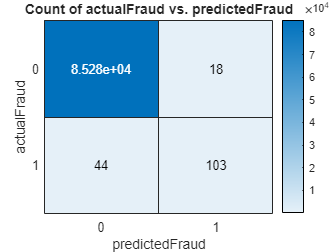


actualFraud = data2_test.Class;
T = table(predictedFraud,actualFraud);
heatmap(T,'predictedFraud','actualFraud');

accuracy = sum(T.predictedFraud == T.actualFraud)/height(T)

accuracy = 0.9993

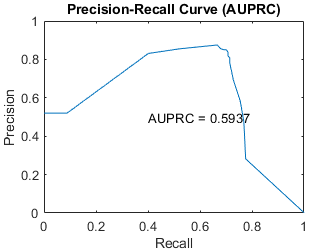


AUPRC = plotAUPRC(data2_test.Class,scores,'1');

function AUPRC = plotAUPRC(response,scores,positiveClass)
% This function is for calculating Area Under the Precision-Recall Curve
% (AUPRC). It also plots the Precision-Recall Curve where

% Calculate recall(X) and precision (Y)
[X,Y] = perfcurve(response,scores(:,2),positiveClass,'xCrit','reca','yCrit','prec');

% sort data (based on accending order of X)
[X, idx] = sort(X);
Y = Y(idx);

% Remove invalid data (Y)
idxNaN = isnan(Y);
X(idxNaN) = [];
Y(idxNaN) = [];

% If X doesn't start at zero, connect Y using a horizontal line
if X(1) ~= 0
    Y = [Y(1); Y];
    X = [0; X];
end

% Calculate Area Under the Precision-Recall Curve
AUPRC = trapz(X,Y); 

% Plot the Precision-Recall Curve
plot(X,Y);
xlabel('Recall')
ylabel('Precision')
title('Precision-Recall Curve (AUPRC)')
text(0.4,0.5,['AUPRC = ' num2str(round(AUPRC,4))])
end
